three different axial positions as shown in Figure 5. 

Thestern appendage position with the appendage trailing edge at

x=13.146284 Ft (4.007 m) is denoted the baseline stern appendage

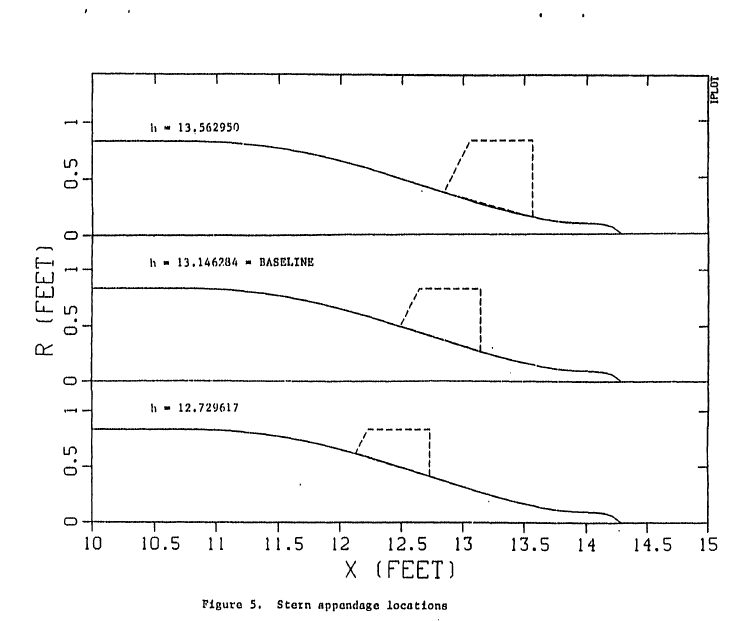

**H Values Selection**

% Parameters

Rmax = 5 / 6;

h = 12.729617 % Use to select the value of h

h = 12.7296

**Tail Equations**

% Initial values y, C
ymax = Rmax;
y = 0:0.001:ymax;
C = -0.466308 * y + 0.88859;

% Calculate xmin and xmax
xmax = h;
xmin = xmax - C;
xmax = ones(size(xmin)) * h;
xdivision = 60;
XmaxElement = max(xmax);
Xstep = (XmaxElement - xmin) / xdivision;

% Initialize an empty matrix X
X = zeros(xdivision, numel(xmax));

% Fill the first row with xmin
X(1, :) = xmin;

% Fill the last row with xmax
X(end, :) = xmax;

% Fill the remaining rows with values increasing from xmin to xmax
for i = 2:xdivision-1
    % Calculate the current row values based on xmin and xmax
    X(i, :) = xmin + (i-1) * (xmax - xmin) / (xdivision - 1);
end

% Full matrix y, C
C = repmat(C, size(X, 1), 1);
y = repmat(y, size(X, 1), 1);

% Calculate E, Z
E = ((X - h) ./ C) + 1;
z = (0.29690 * sqrt(E)) - (0.12600 * E) - (0.35160 * (E.^2)) + (0.28520 * (E.^3)) - (0.10450 * (E.^4));
z = real(z);

**3D Surface  Plot**

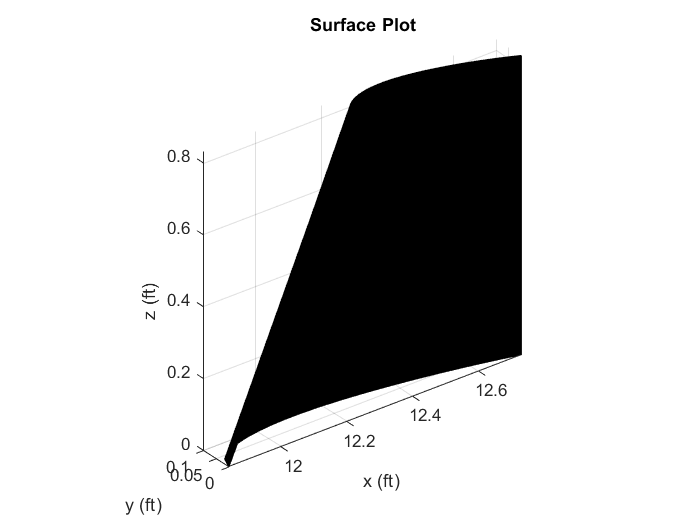

% Plotting surface
figure;
surf(X, z, y);
axis equal;
xlabel('x (ft)');
ylabel('y (ft)');
zlabel('z (ft)');
title('Surface Plot');

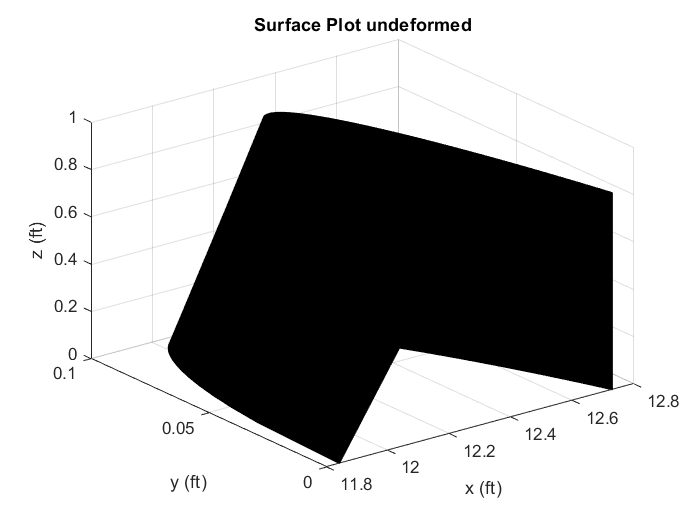

surf(X,z,y)
xlabel('x (ft)');
ylabel('y (ft)');
zlabel('z (ft)');
title('Surface Plot undeformed');

**File Export**

% Save the concatenated matrix as a CSV file
exportXYZtoCSV('XYZ_data_Tail.csv', X, z, y);